# IRS-assisted link in 28GHz band

This example shows how to model the response of an intelligent reflecting surface (IRS) using full-wave electromagnetic simulation. The IRS, also known as the reconfigurable intelligent surface (RIS), large intelligent surface (LIS), or metasurface, has garnered significant interest in the wireless communication community. The IRS consists of a large array of subwavelength unit cell elements which can manipulate the phase, amplitude, polarization, or frequency of the incident signal. If an obstacle blocks the direct path between the base station (BS) and the user equipment (UE), the parasitic reflection of the IRS can provide an alternative path for signal transmission, as this figure shows. An external phase control mechanism can be integrated to control the reflection characteristics of the IRS.

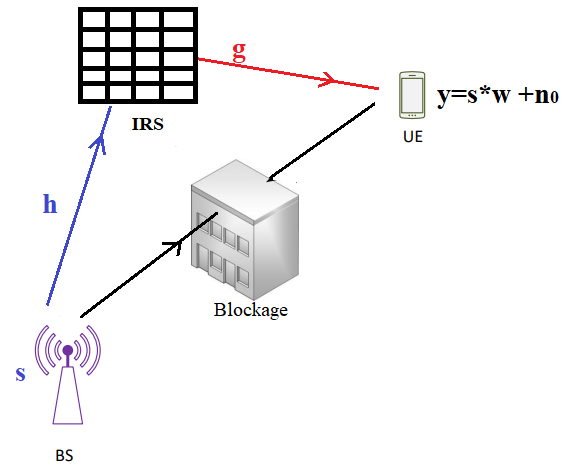

The inclusion of the RIS provides a two-segment indirect path to the signal traveling between the BS and the UE. The first segment covers the path between the BS and the IRS. The second segment covers the path between the IRS and the UE. The channel matrix of these two signal paths depends on the geometry and the electromagnetic reflection properties of the IRS.

The signal received at the UE is represented mathematically in [1] using this equation.

$r=sw+n_0=s\frac{\sqrt{G_rG_uG_tA_rA_u}}{4\pi}\sum_{n=1}^N \frac{\sqrt{\tilde{F}_n}R}{d_{tn}d_{rn}}e^\frac{-j2\pi(d_{tn}+d_{rn})}{\lambda}+n_0$,

where

- 
$$R=[R_1~R_2~......R_n]^T.$$


- $G_u$ is the embedded gain of the $n^{th}$ IRS element.

- $G_t$ is the embedded gain of the BS transmitter.

- $G_r$ is the embedded gain of the UE receiver.

- $F_n=F_n^tF_n^rF_{n}^{tx}F^{rx}_n$ is the product of the normalized power patterns of the BS, UE, and IRS.

- $d_t$ is the distance between the BS and the $n^{th}$ IRS element.

- $d_r$ is the distance between the UE and the $n^{th}$ IRS element.

- $A_r$ is the  effective aperture area of the UE.

- $A_u$ is the effective aperture area of the $n^{th}$ IRS element.

- $\lambda$ is the free-space wavelength.

For this example, assume that the IRS has $$N$$ unit cell elements. The complex reflection coefficient of the $n^{th}$ IRS element is denoted by $R_n=R^{mag}_n e^{j\tau_n}$.

The reflection coefficients of the IRS depend on these factors:

- Direction and polarization of the incoming signal towards the IRS.

- Direction and polarization of the outgoing signal from the IRS.

- Material properties and geometry of the IRS.

This example focuses on varying the incident signal configurations and determining the corresponding reflection characteristics.

Assume that $d_{tn}$ and $d_{rn}$ are in the far-field range. You can abstract the IRS as [infiniteArray](docid:antenna_ref#bvfg_q0-1) catalog element with a [planeWaveExcitation](docid:antenna_ref#bvj2_xq-1) model.

clc;
clear all;
close all;

addpath('./functions_visualization')
addpath('./functions_calculations')

#### Loading the simulation parameters

Parameters;

#### Depicting  the Scenario

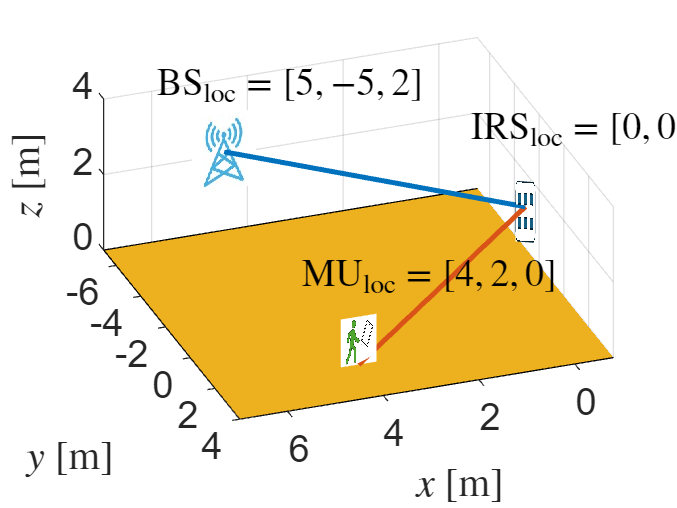

visualizing_scenario

#### Visualizing the reflection coefficient of the IRS

All the coeficients are set to the same amplitude value (reflecting)

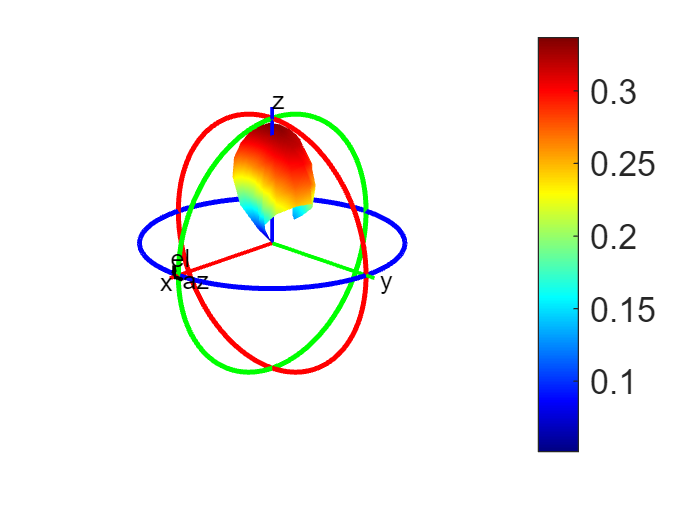

visualizing_reflection_coeff_IRS

#### Visualizing the radiation pattern for the IRS

%Uncomment below for plotting the IRS radiation pattern
% visualizing_radiation_pattern_IRS

#### Visualize Geometry of Unit Cell

Visualize the reflector element using the `show` function. The ground plane length and reflector width determine the periodicity of the IRS.

%visualizing_geometry_IRS

#### Visualize Finite IRS

Visualize a M-by-N finite IRS using the [rectangularArray](docid:antenna_ref#bvcl6lz-1) object and visualize it using the `show` function. Each unit cell element of the periodic IRS comprises a reflector object with a horizontal bowtie antenna as the exciter. 

%visualize_finite_IRS

#### Evaluating the fingerprint

IRS_5G_1MU

ans = 0.1023

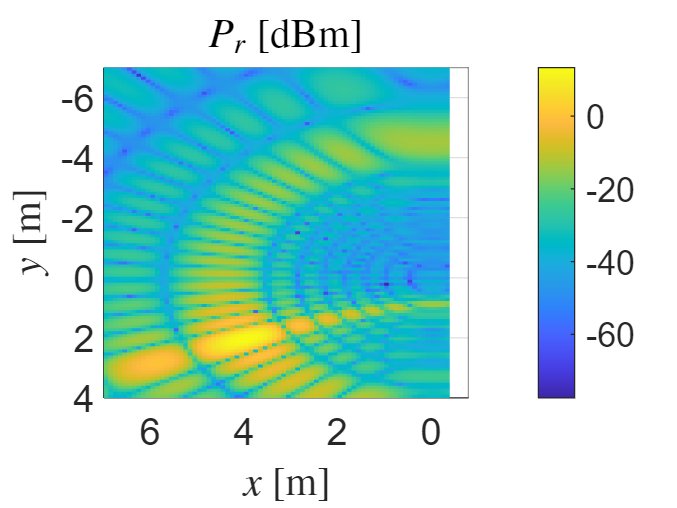


visualizing_fingerprint